We measure the convergence rate for piecewise linear interpolation of $e^{\sin 7x}$.

f = @(x) exp(sin(7*x));
x = linspace(0,1,10001)';  % sample the difference at many points
n_ = 2.^(3:10)';
err_ = 0*n_;

for i = 1:length(n_)
    n = n_(i);
    t = linspace(0,1,n+1)';   % interpolation nodes
    p = plinterp(t,f(t));
    err = max(abs( f(x) - p(x) ));
    err_(i) = err;
end

Since we expect convergence that is $O(h^2)=O(n^{-2})$, we use a log-log graph of error and expect a straight line of slope $-2$.

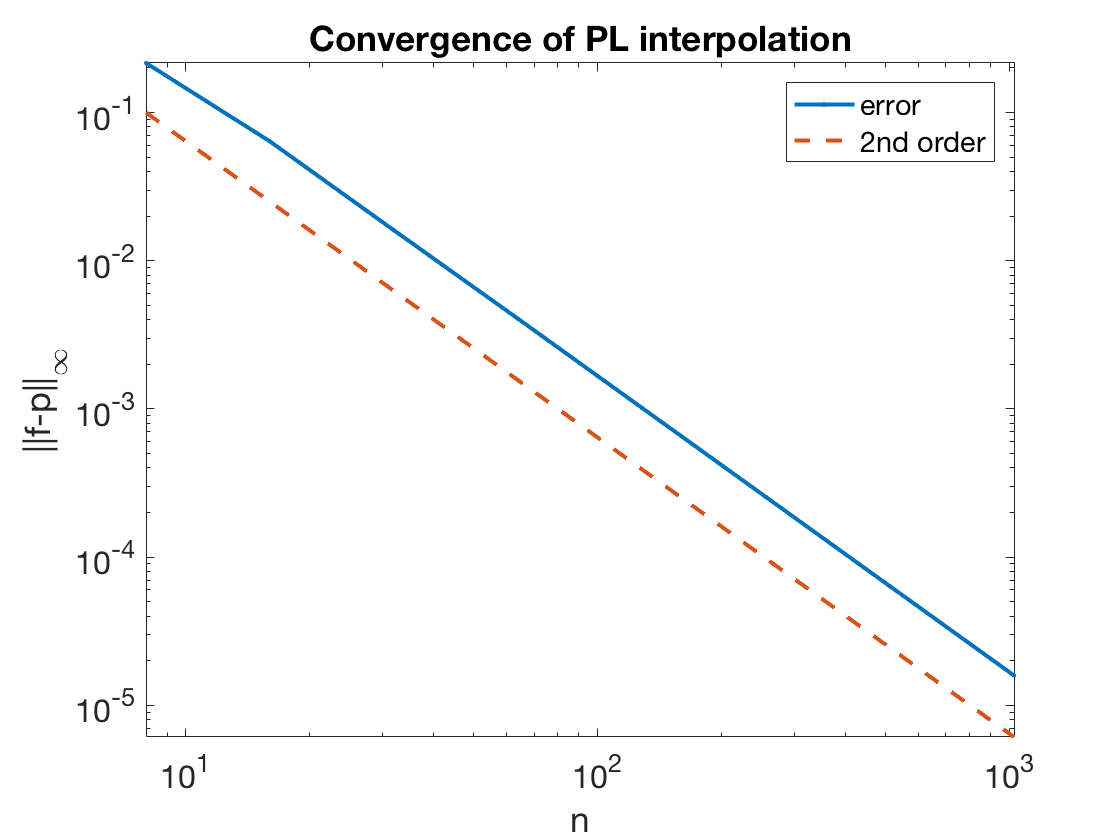

loglog( n_, err_, '.-' )
hold on, loglog( n_, 0.1*(n_/n_(1)).^(-2), '--' )
xlabel('n'), ylabel('||f-p||_\infty')     % ignore this line
title('Convergence of PL interpolation')     % ignore this line
legend('error','2nd order')     % ignore this line
axis tight    % ignore this line